## Part (b) Plotting

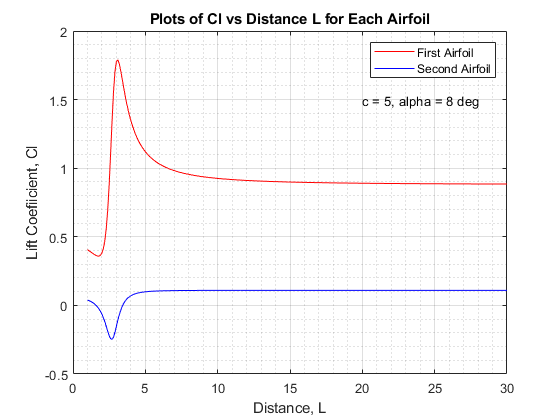

% Setting variables
c = 5; % chord length
alpha = 0.14; % radiant (8 degrees)
L = 1:0.1:30;

% Declaring lift coefficients for each airfoil
n1 = 16 * (alpha+1)^2 .* L.^4 + 8 * c^2 * (alpha^2-1) * L.^2 + c^4;
d1 = 16 * (alpha+1)^2 .* L.^4 + 4 * c^2 * (2*alpha^2-3) * L.^2 + 2 * c^4;
cl1 = 2 * pi  * alpha .* n1 ./ d1;

n2 = 16 * (alpha+1)^2 .* L.^4 + 4 * c^2 * (alpha^2-3) * L.^2 + c^4;
d2 = 128 * (alpha+1)^2 .* L.^4 + 32 * c^2 * (2*alpha^2-3) * L.^2 + 16 * c^4;
cl2 = 2 * pi * alpha .* n2 ./ d2;

% Plotting 
fig1 = figure(1);
plot(L, cl1, '-r')
title("Plots of Cl vs Distance L for Each Airfoil")
xlabel('Distance, L')
ylabel('Lift Coefiicient, Cl')
grid on
grid minor
box on
hold on
plot(L, cl2, '-b')
hold off
legend('First Airfoil', 'Second Airfoil')
txt = 'c = 5, alpha = 8 deg';
text(20, 1.5,txt)